# SISY Test2 Solution

(exercise solved at home - dqtm HS18)

## EXERCISE-1 : Fourier Transformation and Modulation Property

Comment: in this exercise we will not calculate spectrum with FFT. 

But rather with the FT-definitions and properties.

Plus exercise how to deal with complex functions!

clear all, close all; clc;
display('Test-1 , Exercise-1')

Test-1 , Exercise-1


(A)

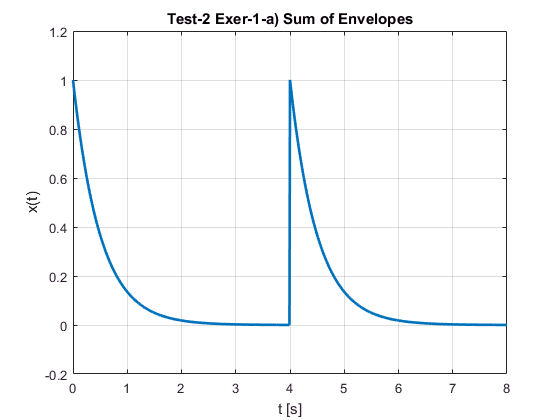

% PARAMETERS
t = 0:0.01:8;
E_t4 = double(t>=4);

% DEFINITIONS
x1_t = exp(-t./0.5);
x2_t = exp(-(t-4)./0.5).*E_t4;
x_t = x1_t + x2_t;

% PLOTS
plot(t,x_t,'LineWidth',2), grid
xlabel('t [s]'),ylabel('x(t)')
title('Test-2 Exer-1-a) Sum of Envelopes')
axis([0 8 -0.2 1.2])

==========================================================

(B)  Hint: Calculate X1(w) with the FT-integral, and X2(w) with the properties and then sum up.

Result:            $X(\omega) = \frac {1 + e^ {-j\omega4}}
                             {j\omega + 2}$

==========================================================

(C)     $X(\omega) =0$        when           ${1 + e^ {-j\omega4}} = 0$        (numerator equals 0)

          or                            ${ e^ {-j\omega4}} = -1$

         which means            $\omega \cdot 4 = \pm\pi ; \pm3\pi ; \pm5\pi; ...$

         or                             $\omega = \frac{\pm\pi}{4} ; 
                \frac{\pm3\pi}{4} ; 
                \frac{\pm5\pi}{4} ; 
                ...
$

choose an adequate w range for you to visualise abs(Y1(w))

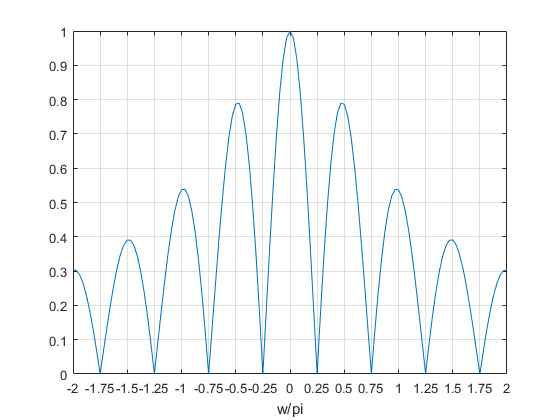

w = -2*pi: pi/32 : 2*pi;
X1_w = (1 + exp(-j*w*4))./(2+j*w);
figure();
plot(w/pi,abs(X1_w)),grid on        % take w/pi as values for horizontal axis
xticks([-2:1/4:2]); xlabel('w/pi')  % in order to get readable scale

==========================================================

(D)    $Y_1(\omega) = \frac{1}{2} \cdot
            \lbrack
            X_1(\omega-\omega_0) +
             X_1(\omega+\omega_0) 
            \rbrack$

Since         $\omega_0 = 2\pi \cdot 100 
                    \cong 628\enspace rad/s$

choose an adequate w range for you to visualise abs(Y1(w))

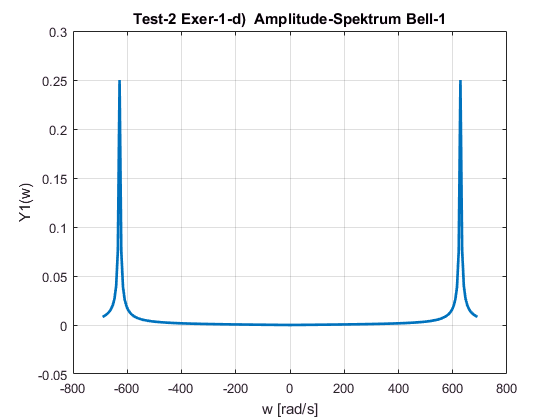

w=2*pi*[-110:1:110];
w0 =2*pi*100;
Y1_w = 0.5*( 1./(2+j*(w-w0)) + 1./(2+j*(w+w0)) );

figure
plot(w,abs(Y1_w),'LineWidth',2),grid
xlabel('w [rad/s]'),ylabel('Y1(w)')
title('Test-2 Exer-1-d)  Amplitude-Spektrum Bell-1')
axis([-800 800 -0.05 0.3])

## **Exercise 2 ***The Uncertainty Principle (or Time-Bandwidth Produkt)*

`Another phrasing as in original assignment, but equivalent: `

`Generally speaking, the more concentrated x (t) is, the more spread out its Fourier transform X(f) must be. In particular, the scaling property of the Fourier transform may be seen as saying: if we squeeze a function in t, its Fourier transform stretches out in f  (and vice versa).`

(a)   Let us experiment with the Uncertainty Principle as expressed above. Define in Matlab three rectangle functions x1(t), x2(t) and x3(t), corresponding to the time function in the left side of figure 1 below. 

*Hint: Define a time vector with exactly 1’000 points, and a sampling frequency of 5kHz. In the function x1(t) all the points are equal to ‘1’, in x2(t) half of the points, and in x3(t) one fourth of the points are equal to ‘1’. You can use for example the functions ones() and zeros(), and concatenate the vectors together. *

(b)   Use the FFT to calculate the corresponding spectra X1(f), X2(f) and X3(f), and generate a plot of the amplitude spectra. Explain the differences among these spectra based on the property time-bandwidth product. 

*Hint: Use the command xlim(), to zoom around and fix the frequency range [0; 100]Hz . *

* In the next exercise, you will use these rectangular pulses as envelope curves for a carrier signal. *

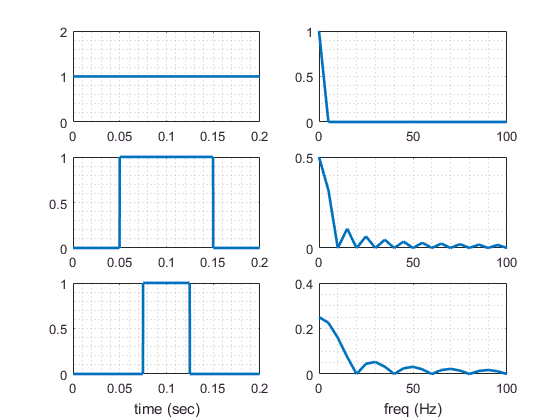

clear all, close all, clc;

% PARAMETERS
N = 1000;           % number of points
Fs = 5000;          % sampling freq
Ts = 1/Fs;          % sampling period

aux = 0:1:N-1;      % auxiliary vector
t = Ts * aux;       % time vector
f = (Fs/N) * aux;   % freq vector

% FUNCTIONS
x1_t = ones(1,N);
x2_t = [zeros(1,N/4),ones(1,N/2),zeros(1,N/4)];
x3_t = [zeros(1,3*N/8),ones(1,N/4),zeros(1,3*N/8)];

X1_f = (1/N)*fft(x1_t);
X2_f = (1/N)*fft(x2_t);
X3_f = (1/N)*fft(x3_t);

figure()
% PLOTS
subplot(321), plot(t,x1_t,'LineWidth',2), grid minor;
subplot(323), plot(t,x2_t,'LineWidth',2), grid minor;
subplot(325), plot(t,x3_t,'LineWidth',2), grid minor; 
xlabel('time (sec)')

subplot(322), plot(f,abs(X1_f),'LineWidth',2), grid minor,xlim([0 100]);
subplot(324), plot(f,abs(X2_f),'LineWidth',2), grid minor,xlim([0 100]);
subplot(326), plot(f,abs(X3_f),'LineWidth',2), grid minor,xlim([0 100]);
xlabel('freq (Hz)')

## **Exercise 3 ***The Frequency Shift Property*

(a)   Define now the signals y1(t), y2(t) and y3(t), which correspond to the multiplication of the envelope curves x1(t), x2(t) and x3(t) with a sinus wave of frequency 400Hz. 

(b)   Calculate and plot the spectra Y1(f), Y2(f) and Y3(f), and use *xlim()* to zoom around the interesting part of the spectrum. Where is it now (which frequency range) ? 

Check the frequency shift property and explain the differences among the Xn(f) and Yn(f) spectra. 

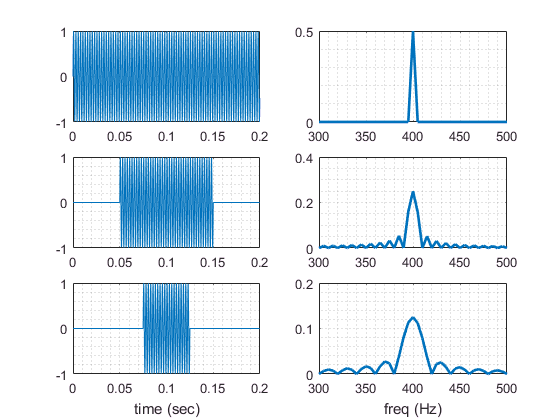

% FUNCTIONS
m_t = sin(2*pi*400*t);
y1_t = x1_t.*m_t;
y2_t = x2_t.*m_t;
y3_t = x3_t.*m_t;

Y1_f = (1/N)*fft(y1_t);
Y2_f = (1/N)*fft(y2_t);
Y3_f = (1/N)*fft(y3_t);

figure()
% PLOTS
subplot(321), plot(t,y1_t), grid minor;
subplot(323), plot(t,y2_t), grid minor;
subplot(325), plot(t,y3_t), grid minor; 
xlabel('time (sec)')

subplot(322), plot(f,abs(Y1_f),'LineWidth',2), grid minor,xlim([300 500]);
subplot(324), plot(f,abs(Y2_f),'LineWidth',2), grid minor,xlim([300 500]);
subplot(326), plot(f,abs(Y3_f),'LineWidth',2), grid minor,xlim([300 500]);
xlabel('freq (Hz)')

(c)   How do these spectra change, if you take instead of the rectangular envelope curves, three new envelope curves with the form of slow sinuses with frequency 5Hz, 10Hz and 20Hz ? You can consider these envelope curves last over the entire time window [0 0.2]s 

Justify your answer with a plot in Matlab. 

% FUNCTIONS
s1_t = cos(2*pi*5*t);
s2_t = cos(2*pi*10*t);
s3_t = cos(2*pi*20*t);

m_t = sin(2*pi*400*t);
y1_t = s1_t.*m_t;
y2_t = s2_t.*m_t;
y3_t = s3_t.*m_t;

Y1_f = (1/N)*fft(y1_t);
Y2_f = (1/N)*fft(y2_t);
Y3_f = (1/N)*fft(y3_t);

figure()
% PLOTS
subplot(321), plot(t,y1_t), grid minor;
subplot(323), plot(t,y2_t), grid minor;
subplot(325), plot(t,y3_t), grid minor; 
xlabel('time (sec)')

subplot(322), plot(f,abs(Y1_f),'LineWidth',2), grid minor,xlim([300 500]);
subplot(324), plot(f,abs(Y2_f),'LineWidth',2), grid minor,xlim([300 500]);
subplot(326), plot(f,abs(Y3_f),'LineWidth',2), grid minor,xlim([300 500]);
xlabel('freq (Hz)')